fileName = "data/c3x7_s1602_l48.m";

fileName = "data/c3x7_s1602_l48.m"

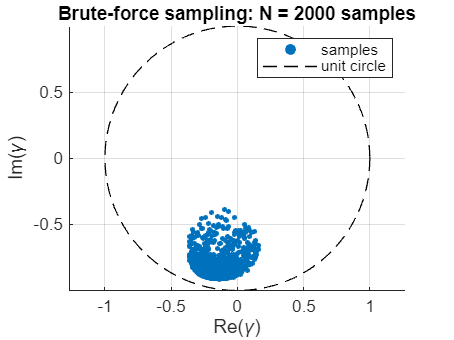

N = 2000;
gamma_vals = BruteForce(fileName, N);

% --- Plot the brute-force sampled points ---
figure('Name','Brute-force coherence sampling','NumberTitle','off');
scatter(real(gamma_vals), imag(gamma_vals), 8, 'filled'); axis equal; grid on;
xlabel('Re(\gamma)'); ylabel('Im(\gamma)');
title(sprintf('Brute-force sampling: N = %d samples', N));
% draw unit circle for reference
hold on; th = linspace(0,2*pi,500); plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);
legend('samples','unit circle');